Fórmulario para primer examen:

- Bisección

- Golden Search

- Interpolación Lineal

- Muller

- Newton R

- Newton R Optimizado

- Secante

- Bungee

- FUN IEEE

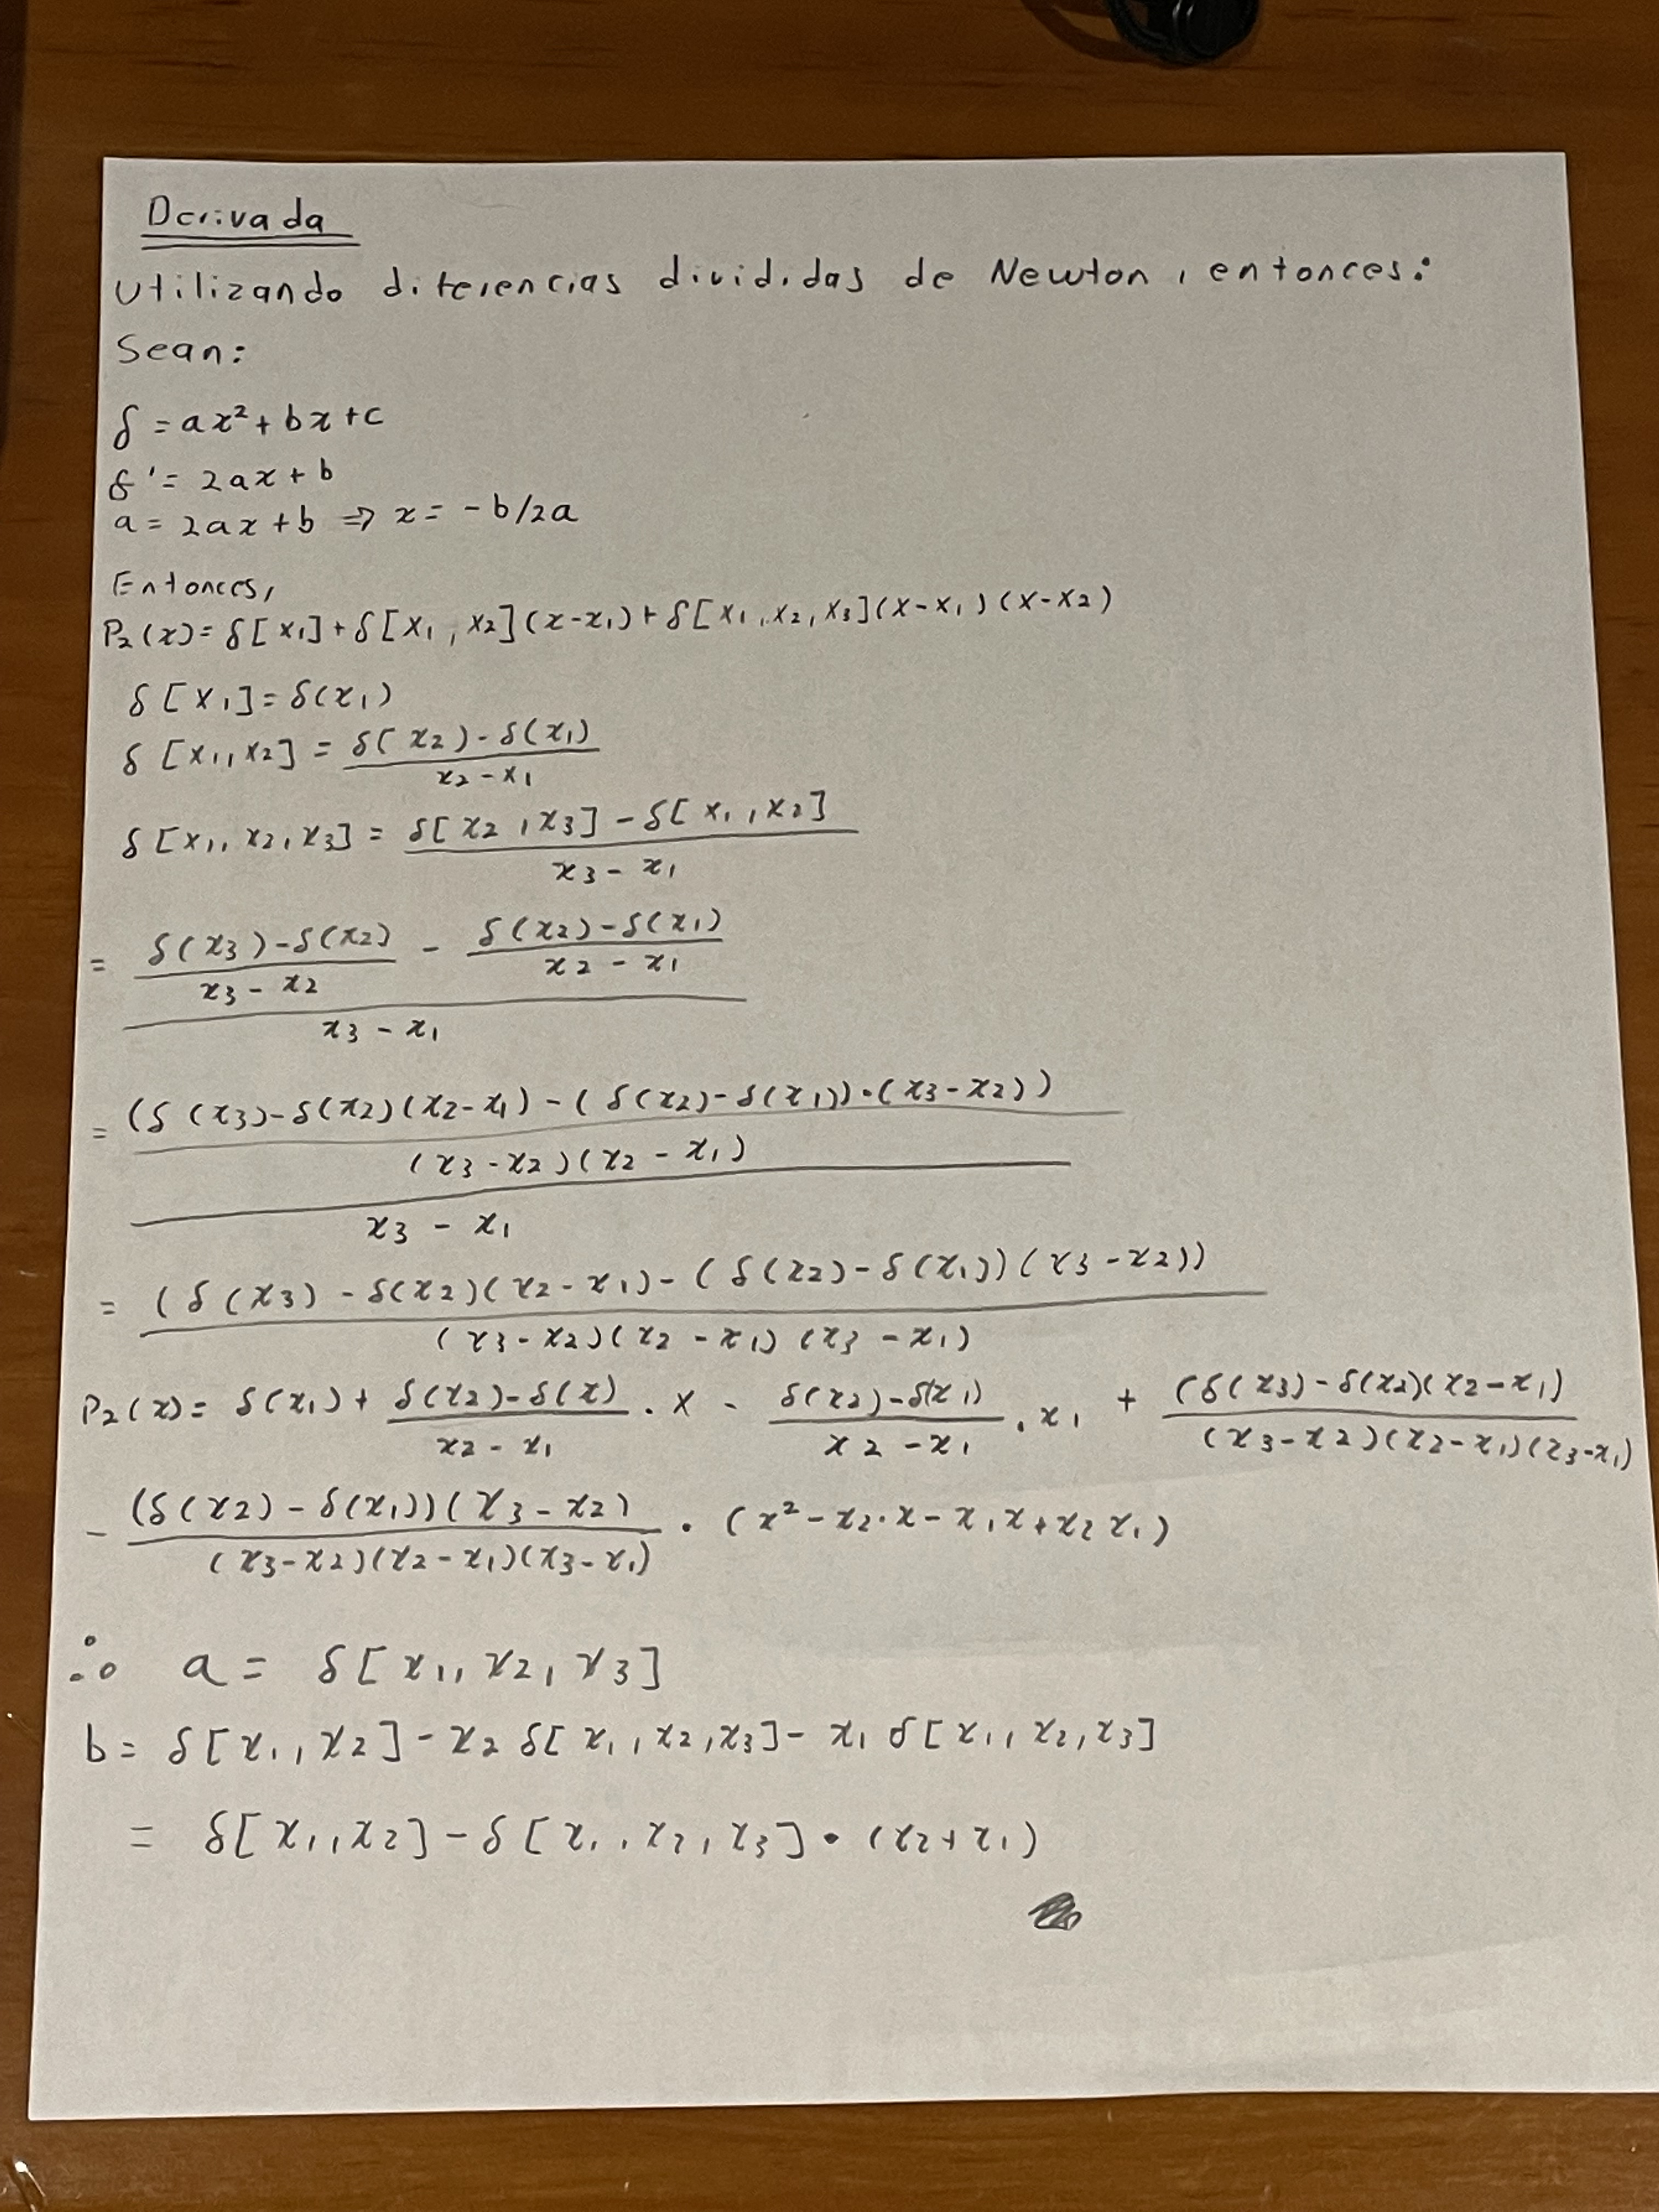

b = '0011111111110000000000000000000000000000000000000000000000000000';
x = binary2Double(b)

f = @(x) -12 - 21*x + 18*x.^2 - 2.75*x.^3;

[x, i] = interpolacionLineal(f, -1, 0)
[x, i] = newtonRaphson(f, -1, 0)

Vd = 30;

x = -0.4147

i = 17

R = 3;

x = -0.4147

i = 4

vol = @(h) (pi * h .^ 2) .* ((3 * R - h) / 3) - Vd;
[h, i] = secante(vol, 1, 3)
[h, i] = Muller(vol, 1, 3, 5)


Bungee jumper 

Determina la masa máxima que puede tener un saltador si, por motivos de seguridad, la velocidad no puede 

exceder de 33m/s a los 4s. 

g = 9.81;

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

h = 2.0269

i = 7

cd = 0.25;

h = 2.0269

i = 5

vM = 33;
t = 4;
vol = @(m) sqrt(g * m / cd) .* tanh(sqrt(g * cd ./ m) * t);
fplot(vol, [40, 200]);
grid on;
2
mbj = secante(@(m) vol(m) - vM, 60, 80)

function [xr, i] = biseccion(f, xl, xu)
    if sign(f(xl)) * sign(f(xu)) >= 0
        error('f(a) * f(b) < 0 no se satisface.')
    end
    
    MAX_ITER = 55;
    TOLER = eps;
    xr = (xl + xu) / 2; 
    fx = f(xr);
    i = 0;
    
    while fx ~= 0 && abs((xu - xl) / xu) > TOLER && i < MAX_ITER
        if sign(f(xl)) == sign(fx)
            xl = xr;
        else
            xu = xr;
        end 
        xr = (xl + xu) / 2;
        fx = f(xr);
        i = i + 1;
    end
end

function [x, i] = goldenSS(f, a, b)
    TOL = eps;
    MAX_ITER = 53;
    x = (a + b) / 2;
    g = (1 + sqrt(5)) / 2 - 1;
    dist = g * (b - a);
    x1 = a + dist;
    fx1 = f(x1);
    x2 = b - dist;
    fx2 = f(x2);
    i = 0;
    flag = true;
    while flag
        dist = g * dist;
        if fx1 < fx2
            a = x2;
            x2 = x1;
            fx2 = fx1;
            x1 = a + dist;
            fx1 = f(x1);
        else
            b = x1;
            x1 = x2;
            fx1 = fx2;
            x2 = b - dist;
            fx2 = f(x2);
        end
        x = (a + b) / 2;   
        i = i + 1;
        flag = abs((b - a) / x) > TOL && i < MAX_ITER;     
    end
end

function [x,i]=interpolacionLineal(f,a,b)
    i=0;
    iMAX=52;
    TolMax=eps;
    ban=true;
    fa=f(a);
    fb=f(b);
    while(ban)
        x=b-(a-b)/(fa-fb)*fb;
        fx=f(x);
        if(not(sign(fb)==sign(fx)))
            b=x;
            fb=fx;
        else
            a=x;
            fa=fx;
        end
        i=i+1;
        ban=abs(1-b/a)>TolMax&&i<iMAX;
    end
end

function [x,i]= Muller(f,p1,p2,p3) 
    iMAX=52;
    TolMax=sqrt(eps);
    i=0;
    f1=f(p1);
    f2=f(p2);
    condition=true;
    while(condition)
        f3=f(p3);
        Pol2=polyfit([p1,p2,p3],[f1,f2,f3],2);
        r=roots(Pol2);
        if(abs(p3-r(1))<abs(p3-r(2)))
            x=r(1);
        else
            x=r(2);
        end
        f1=f2; f2=f3; 
        p1=p2; p2=p3; p3=x;
        i=i+1;
        condition=abs((x-p2)/x)>TolMax && i<iMAX;
    end
end

function [x, i] = newtonRaphson(f, a, b)
    REL_TOL = sqrt(eps);
    MAX_ITER = 53;
    x = (a + b) / 2;
    df = matlabFunction(diff(sym(f)));
    
    if nargin(df) == 0
        df = @(x) df();
    end
    
    i = 0;
    flag = true;
    while flag
        xp = x;
        dx = f(xp) / df(xp);
        x = xp - dx;
        i = i + 1;
        flag = i < MAX_ITER && abs(dx / x) > REL_TOL;     
    end
end

function [x, i, m] = newtonOpt(f, a, b)
    TOL = eps;
    MAX_ITER = 53;
    x = (a + b) / 2;
    df = diff(sym(f));
    ddf = matlabFunction(diff(df));
    df = matlabFunction(df);
     
    if nargin(ddf) == 0
        ddf = @(x) ddf();
    end
    
    i = 0;
    flag = true;
    while flag
        xp = x;
        dx = df(xp) / ddf(xp);
        x = xp - dx;
        i = i + 1;
        flag = abs((dx / x)) > TOL && i < MAX_ITER;     
    end
    m = ddf(x) > 0;
end

function [x, i] = secante(f, xp, x)
    MAX_ITER = 53;
    REL_TOL = eps;
    i = 0;
    fx = f(x);
    fxp = f(xp);
    flag = true;
    while flag
        sn = (fx - fxp) / (x - xp);
        xp = x;
        fxp = fx;
        x = xp - fxp / sn;
        fx = f(x);
        i = i + 1;
        flag = i < MAX_ITER && abs((x - xp) / x) > REL_TOL;
    end
end

function x = binary2Double(b)

% Extract the sign, exponent, and mantissa bits from the string.
s = b(1)
exp = b(2:12)
m = b(13:64)
% Convert the bits to decimal values.
edec = bin2dec(exp)
bias = edec - 1023
mdec = bin2dec(m) + 1 
% Convert to a real number using the IEEE Standard 754.
x = ((-1)^s)*(2^bias)*(mdec)
end